## MAS 416 - Lecture 4 - Problem 3

clc; clear all; close all;

d = 42/1000; % m, diameter of cylinder
d_r = 30/1000; % m, diameter of rod inside cylinder
L_0 = 1600/1000; % m, stroke length

A_1 = pi/4 * d^2; % Area of cylinder
A_2 = A_1 - pi/4 * d_r^2; % Area of donut cylinder

m_1 = 3000; % kg
m_2 = 5000; % kg

Cd = 0.6; % discharge coefficient
A_d1 = 9 * 10^-6; % m, discharge area
A_d3 = A_d1;

A_d2 = 5 * 10^-6; % m, discharge area
A_d4 = A_d2;

rho = 875; % kg/m^3
beta = 830 * 10^6; % Pa, stiffness of oil

V_0 = 1 * 10^-3; % m^3, constant inlet volume

x1 = 200/1000; % m
x2 = x1;

x1Dot = 0;     % m/s
x2Dot = x1Dot; % m/s

p0 = 0;
p1 = p0;  % Pa
p2 = p0; % Pa
p3 = p0; % Pa
p4 = p0; % Pa

F_f1_max = 12*10^3; % N
F_f2_max = 20*10^3; % N
F_f1 = 0; % N
F_f2 = 0; % N

Q_0_max = 25 * (10^-3 / 60); % m^3/s

t = 0;       % s
simTime = 2; % s
dt = 10^-4;  % s
idx = 1;     % -

while t <= simTime
    if(t<=0.25)
        Q_0 = t/0.25 * Q_0_max;
    elseif(t >= 0.25 && t <= 1.25)
        Q_0 = Q_0_max;
    elseif(t >= 1.25 && t <= 1.5)
        
        tm = t-(1.5-0.25);
        Q_0 = Q_0_max * (1-(tm/0.25));
        %Q_0 = Q_0_max * (1-(t-(0.25+1))/0.25);
    else
        Q_0 = 0;
    end


$$\begin{array}{l}
L={\textrm{dm}}^3 \\
{10}^3 \;{\textrm{dm}}^3 =m^3 \Longrightarrow \frac{m^{\;3} }{{10}^3 \;{\textrm{dm}}^3 }\\
Q_0 =Q_0 \cdot \frac{{\textrm{dm}}^3 }{\min }\cdot \frac{m^{\;3} }{{10}^3 \;{\textrm{dm}}^3 }=Q_0 \cdot \frac{m^3 }{\min }\cdot {10}^{-3} \\
\min =60s\Longrightarrow \frac{\min }{60s}\\
Q_0 =Q_0 \cdot \frac{m^3 }{\min }\cdot {10}^{-3} \cdot \frac{\min }{60s}=Q_0 \cdot m^3 \cdot \frac{{10}^{-3} }{60s}
\end{array}$$


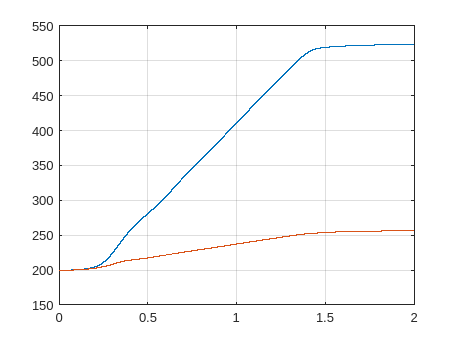

    % Calculate friction forces
    % Mass m1
    if(x1Dot < -0.05)
        F_f1 = -F_f1_max;
    elseif(x1Dot < 0.05)
        F_f1 = x1Dot/0.05 * F_f1_max;
    else
        F_f1 = F_f1_max;
    end

    % Mass m2
    if(x2Dot < -0.05)
        F_f2 = -F_f2_max;
    elseif(x2Dot < 0.05)
        F_f2 = x2Dot/0.05 * F_f2_max;
    else
        F_f2 = F_f2_max;
    end

    % Calculate volumes
    V_1 = A_1*x2;
    V_2 = A_2*(L_0-x2);
    V_3 = A_1*x1;
    V_4 = A_2*(L_0-x1);

    % Calculate flows
    Q_1 = Cd * A_d1 * sign(p0-p1)*sqrt(2/rho * abs(p0-p1));
    Q_2 = Cd * A_d2 * sign(p2)*sqrt(2/rho * abs(p2));
    Q_3 = Cd * A_d3 * sign(p0-p3)*sqrt(2/rho * abs(p0-p3));
    Q_4 = Cd * A_d4 * sign(p4)*sqrt(2/rho * abs(p4));
        
    % Calculate change in pressures
    p0Dot = beta/V_0 * (Q_0 - Q_1 - Q_3);
    p1Dot = beta/V_1 * (Q_1-A_1*x2Dot);
    p2Dot = beta/V_2 * (A_2*x2Dot-Q_2);
    p3Dot = beta/V_3 * (Q_3-A_1*x1Dot);
    p4Dot = beta/V_4 * (A_2*x1Dot-Q_4);

    x1DotDot = (A_1*p3-A_2*p4 - F_f1)/m_1;
    x2DotDot = (A_1*p1-A_2*p2 - F_f2)/m_2;
        
    % Logging
    timePlot(idx) = t;
    x1Plot(idx) = x1*1000;
    x2Plot(idx) = x2*1000;
    p0Plot(idx) = p0/10^5;
    p3Plot(idx) = p3/10^5;
    p4Plot(idx) = p4/10^5;

    % Time integrate
    p0 = p0 + p0Dot * dt;
    p1 = p1 + p1Dot * dt;
    p2 = p2 + p2Dot * dt;
    p3 = p3 + p3Dot * dt;
    p4 = p4 + p4Dot * dt;

    x1 = x1 + x1Dot * dt;
    x2 = x2 + x2Dot * dt;
    x1Dot = x1Dot + x1DotDot * dt;
    x2Dot = x2Dot + x2DotDot * dt;

    t = t + dt;
    idx = idx + 1;
end

plot(timePlot, x1Plot)
hold on
plot(timePlot, x2Plot)
grid

hold off

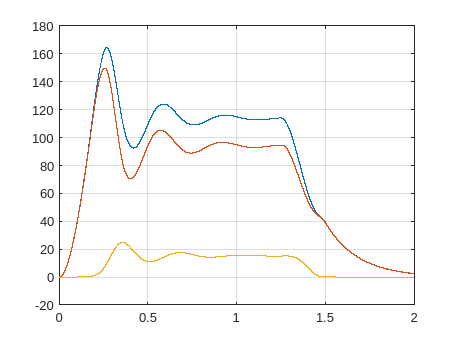

plot(timePlot, p0Plot)
hold on
plot(timePlot, p3Plot)
plot(timePlot, p4Plot)
grid